# live script

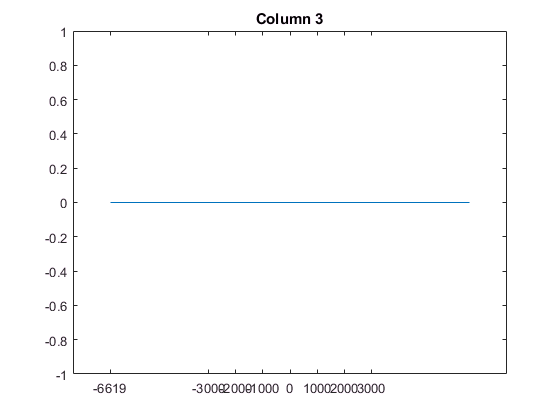

close all
%clear variables
dateString = datestr(now,'mm_dd_yyyy_HH_MM');
%dateString = '05_21_2018_16_21';   
phone1 = csvread(['sensor_data1_' dateString '.csv']);
phone2 = csvread(['sensor_data2_' dateString '.csv']);
col = 3;
ac1 = phone1(2:phone1(1,col),col);
ac2 = phone2(2:phone2(1,col),col);
[acor, lag] = xcorr(ac2, ac1);
[~,I] = max(abs(acor));
lagDiff = lag(I);
figure
plot(lag, acor);
title(['Column ' num2str(col)]);
a3 = gca;
a3.XTick = sort([-3000:1000:3000 lagDiff]);

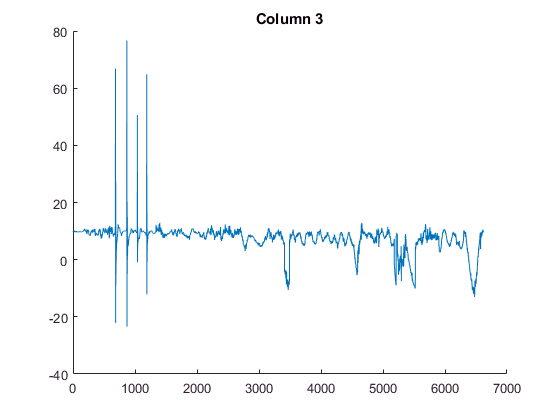

figure
plot(ac1);
hold on
plot(ac2);
title(['Column ' num2str(col)]);

if (lagDiff < 0)
    newData = [(phone1(1,col-2:col)+lagDiff-1);phone1((-lagDiff+1):end,col-2:col)];
    phone1(:,col-2:col) = [newData; zeros(size(phone1,1)-size(newData,1),3)];
else
    newData = [(phone2(1,col-2:col)+lagDiff+1);phone2((lagDiff+1):end,col-2:col)];
    phone2(:,col-2:col) = [newData; zeros(size(phone2,1)-size(newData,1),3)];
end
ac1 = phone1(2:phone1(1,col),col);
ac2 = phone2(2:phone2(1,col),col);
figure
plot(ac1)
hold on
plot(ac2)
title(['Column ' num2str(col)]);